# 4.5 Integral Controllers

## Example 4.5: Continuous Control via the Controller Canonical Form


$$\begin{array}{l}
\dot{\mathbf{x}} =\left\lbrack \begin{array}{ccc}
-0\ldotp 14 & 0\ldotp 33 & -0\ldotp 33\\
0\ldotp 1 & -0\ldotp 28 & 0\\
0 & 1\ldotp 7 & -0\ldotp 77
\end{array}\right\rbrack \mathbf{x}+\left\lbrack \begin{array}{c}
0\\
0\\
-0\ldotp 025
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{ccc}
2 & 0 & 0
\end{array}\right\rbrack \mathbf{x}
\end{array}$$


A = [-0.14 0.33 -0.33;0.1 -0.28 0;0 1.7 -0.77];
B = [0 0 -0.025]';
C = [2 0 0];
D = 0;

E = eig(A);
tau = -1./E(imag(E)==0)

tau =        1.1129


wn = abs(E(imag(E)>0))

wn =       0.26028


zeta = -real(E(imag(E)>0))./wn

zeta =        0.5598



l_cl = [-0.67 -0.67 -0.67]'

l_cl =         -0.67
        -0.67
        -0.67


chP_a = poly(E);
a = chP_a(end:-1:2);
chP_alph = poly(l_cl);
alpha = chP_alph(end:-1:2);
K_cc = alpha-a;

sz = size(B,1);
P = zeros(sz)

P =      0     0     0
     0     0     0
     0     0     0


for i = 1:sz
    if i == 1
        P(:,sz) = B;
    else
        P(:,sz-i+1) = A*P(:,sz-i+2)+chP_a(i)*P(:,sz);
    end
end

K = K_cc/P;
eig(A-B*K)

ans =         -0.67 +          0i
        -0.67 + 8.8882e-07i
        -0.67 - 8.8882e-07i



sys_ss = ss(A-B*K,B,C,D);
sys_tf = tf(sys_ss)


sys_tf =
 
         0.0165 s + 0.00462
  ---------------------------------
  s^3 + 2.01 s^2 + 1.347 s + 0.3008
 
Continuous-time transfer function.



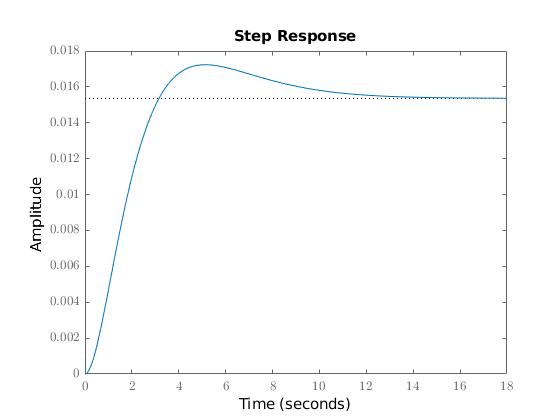

step(sys_ss)

## Example 4.6 Discrete Control via the Controller Canonical Form

tau/5

ans =       0.22257


Ts = 0.2;
F = expm(A*Ts)

F =       0.97295     0.052931    -0.060311
     0.019182       0.9461  -0.00060995
    0.0031422       0.3063       0.8572


syms t
sys_d = c2d(sys_ss,Ts);
G = sys_d.B

G =    0.00014709
   9.9516e-07
   -0.0042638


l_cld = exp(l_cl*Ts)

l_cld =       0.87459
      0.87459
      0.87459


K_d = acker(A,B,l_cld)

K_d =        432.35      -2066.6       152.55


eig(F-G*K)

ans =       0.86123 +          0i
      0.88156 +    0.02052i
      0.88156 -    0.02052i


## Example 4.12 Itegral Control of a Third Order System


$$\begin{array}{l}
\dot{{\mathbf{x}}_a } =\left\lbrack \begin{array}{c}
\dot{\mathbf{x}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
-0\ldotp 14 & 0\ldotp 33 & -0\ldotp 33 & 0\\
0\ldotp 1 & -0\ldotp 28 & 0 & 0\\
0 & 1\ldotp 7 & -0\ldotp 77 & 0\\
-2 & 0 & 0 & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
-0\ldotp 025\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{cccc}
2 & 0 & 0 & 0
\end{array}\right\rbrack {\mathbf{x}}_a 
\end{array}$$



$$\begin{array}{l}
\dot{{\mathbf{x}}_a } =\left\lbrack \begin{array}{c}
\dot{\mathbf{x}} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\mathbf{A} & 0\\
-\mathbf{C} & 0
\end{array}\right\rbrack {\mathbf{x}}_a +\left\lbrack \begin{array}{c}
\mathbf{B}\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
{\mathbf{I}}_r 
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{cc}
\mathbf{C} & 0
\end{array}\right\rbrack {\mathbf{x}}_a 
\end{array}$$
